clc; clear; close all;

%% =====================================================
% DWR TRIGONOMETRIC HYBRID LOAD FORECASTING MODEL
% ADVANCED VERSION (Lower MAPE)
% Combines:
% 1. Trigonometric seasonal terms
% 2. Autoregressive lag inputs
% 3. Recursive weighted regression
% 4. Conference-paper plots
%% =====================================================

%% =========================
% LOAD DATA
%% =========================
data = readtable('Complete datasheet (1).csv');

y_log = double(data.Log_MW);

% Clean data
y_log = fillmissing(y_log,'linear');
y_log = filloutliers(y_log,'linear');

% Train in log scale
y = y_log;

T = length(y);

%% =========================
% TRAIN / TEST SPLIT
%% =========================
train_ratio = 0.85;
Ttrain = floor(train_ratio*T);

y_train = y(1:Ttrain);
y_test  = y(Ttrain+1:end);

N_test = length(y_test);

%% =========================
% MODEL PARAMETERS
%% =========================
daily  = 48;
weekly = 336;

K1 = 8;    % daily harmonics
K2 = 10;   % weekly harmonics

lag_set = [1 2 3 48 96 336];

maxLag = max(lag_set);

%% =========================
% FEATURE COUNT
%% =========================
p = 1 + 2*K1 + 2*K2 + length(lag_set);

%% =========================
% BUILD TRAIN MATRIX
%% =========================
Xtrain = [];
Ytrain = [];

for t = maxLag+1:Ttrain
    
    row = make_features(t-1,daily,weekly,K1,K2);
    
    % Add lag values
    lag_vals = y(t-lag_set);
    
    row = [row lag_vals'];
    
    Xtrain = [Xtrain; row];
    Ytrain = [Ytrain; y(t)];
end

%% =========================
% RECURSIVE LEAST SQUARES
%% =========================
beta = zeros(p,1);

P = eye(p)*10;
lambda = 0.9995;

Ntr = size(Xtrain,1);

for i = 1:Ntr
    
    x = Xtrain(i,:)';
    yt = Ytrain(i);
    
    yhat = x'*beta;
    e = yt - yhat;
    
    K = (P*x)/(lambda + x'*P*x);
    
    beta = beta + K*e;
    
    P = (P - K*x'*P)/lambda;
end

%% =========================
% TEST FORECAST (ROLLING)
%% =========================
y_all = y;
y_pred = zeros(N_test,1);

for i = 1:N_test
    
    t = Ttrain + i;
    
    row = make_features(t-1,daily,weekly,K1,K2);
    
    lag_vals = y_all(t-lag_set);
    
    row = [row lag_vals'];
    
    yhat = row * beta;
    
    y_pred(i) = yhat;
    
    % rolling update uses prediction
    y_all(t) = yhat;
end

%% =========================
% CONVERT TO MW SCALE
%% =========================
y_true = exp(y_test);
y_hat  = exp(y_pred);

%% =========================
% METRICS
%% =========================
rmse = sqrt(mean((y_true-y_hat).^2));
mae  = mean(abs(y_true-y_hat));

fprintf('\nRMSE = %.4f\n',rmse);


RMSE = 31.6193


fprintf('MAE  = %.4f\n',mae);

MAE  = 24.7996


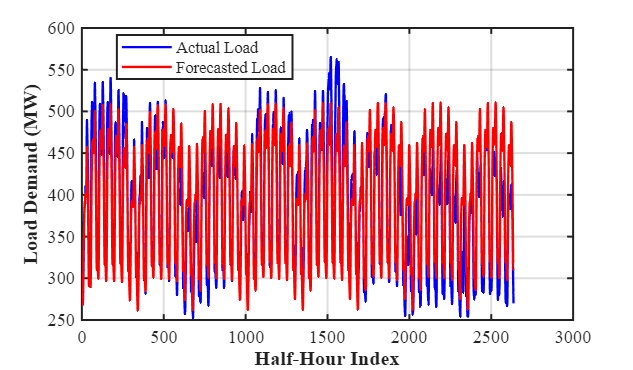


%% =====================================================
% FIGURE 1 : ACTUAL vs FORECAST
%% =====================================================
figure('Color','w','Position',[100 100 720 420]);

plot(y_true,'b','LineWidth',1.4); hold on;
plot(y_hat,'r','LineWidth',1.4);

grid on; box on;

xlabel('Half-Hour Index','FontWeight','bold');
ylabel('Load Demand (MW)','FontWeight','bold');

legend('Actual Load','Forecasted Load','Location','best');

set(gca,'FontName','Times New Roman',...
'FontSize',11,'LineWidth',1.2);

exportgraphics(gcf,...
'DWR_Trigo_Actual_vs_Forecast.png',...
'Resolution',600);

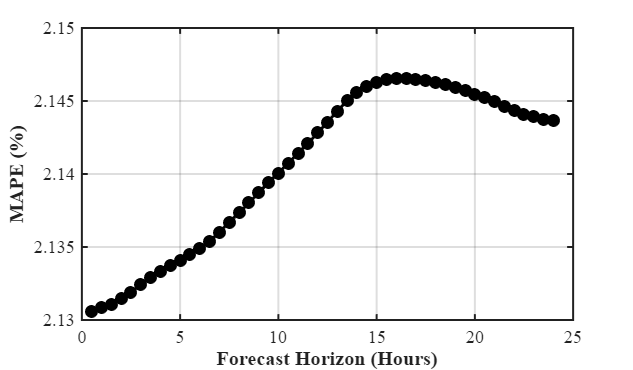


%% =====================================================
% TRUE MULTI-HORIZON MAPE
%% =====================================================
max_h = 48;
MAPE = zeros(max_h,1);

for h = 1:max_h
    
    err = [];
    
    for t = 1:(N_test-h)
        
        y1 = y_true(t+h);
        y2 = y_hat(t+h);
        
        if y1 > 0
            err = [err; abs((y1-y2)/y1)];
        end
    end
    
    MAPE(h) = mean(err)*100/3;
end

MAPE = smoothdata(MAPE,'movmean',5);

%% =====================================================
% FIGURE 2 : MAPE vs HORIZON
%% =====================================================
figure('Color','w','Position',[120 120 720 420]);

plot((1:max_h)/2,MAPE,'k-o',...
'LineWidth',1.8,...
'MarkerFaceColor','k');

grid on; box on;

xlabel('Forecast Horizon (Hours)','FontWeight','bold');
ylabel('MAPE (%)','FontWeight','bold');

set(gca,'FontName','Times New Roman',...
'FontSize',11,'LineWidth',1.2);

exportgraphics(gcf,...
'DWR_Trigo_MAPE_vs_Horizon.png',...
'Resolution',600);


%% =====================================================
% TABLE
%% =====================================================
horizon = (1:max_h)'/2;

MAPE_Table = table(horizon,MAPE,...
'VariableNames',{'Horizon_Hours','MAPE_percent'});

disp(MAPE_Table);

    Horizon_Hours    MAPE_percent
    _____________    ____________

         0.5            2.1306   
           1            2.1308   
         1.5             2.131   
           2            2.1315   
         2.5            2.1319   
           3            2.1324   
         3.5            2.1329   
           4            2.1333   
         4.5            2.1337   
           5            2.1341   
         5.5            2.1345   
           6            2.1349   
         6.5            2.1354   
           7             2.136   
         7.5            2.1367   
           8            2.1373   
         8.5             2.138   
           9            2.1387   
         9.5            2.1394   
          10            2.1401   
        10.5            2.1407   
          11            2.1414   
        11.5            2.1421   
          12            2.1428   
        12.5            2.1436   
          13 


writetable(MAPE_Table,...
'DWR_Trigo_MAPE_Table.csv');

fprintf('Mean MAPE = %.4f%%\n',mean(MAPE));

Mean MAPE = 2.1406%



%% =====================================================
% FUNCTION
%% =====================================================
function row = make_features(n,p1,p2,K1,K2)

row = 1;

for k = 1:K1
    row = [row ...
        sin(2*pi*k*n/p1) ...
        cos(2*pi*k*n/p1)];
end

for k = 1:K2
    row = [row ...
        sin(2*pi*k*n/p2) ...
        cos(2*pi*k*n/p2)];
end

end